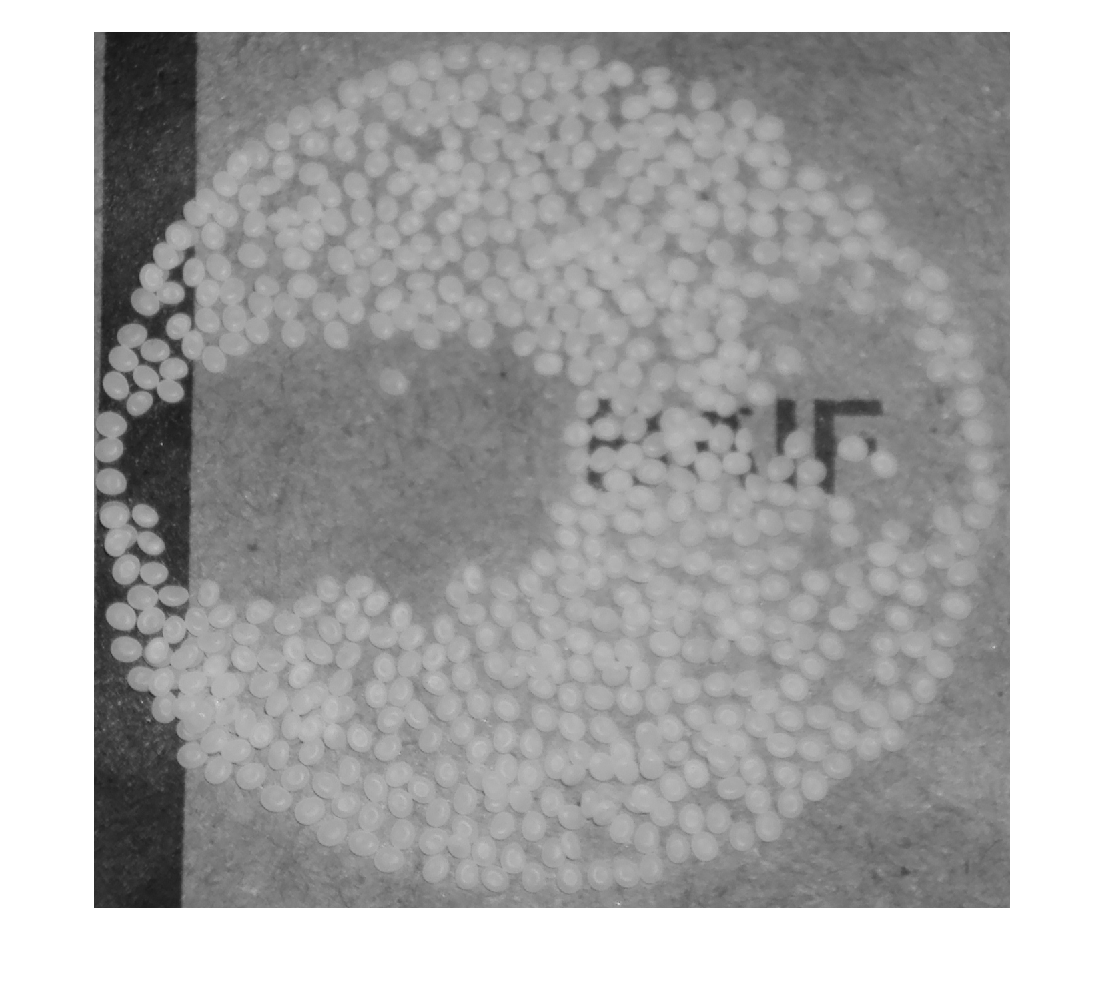

clear; close all; clc;

img = imread('about500.jpg');
%img = imread('about1000.jpg');
%img = imread('about2000.jpg');
img_gray = rgb2gray(img); imshow(img_gray);

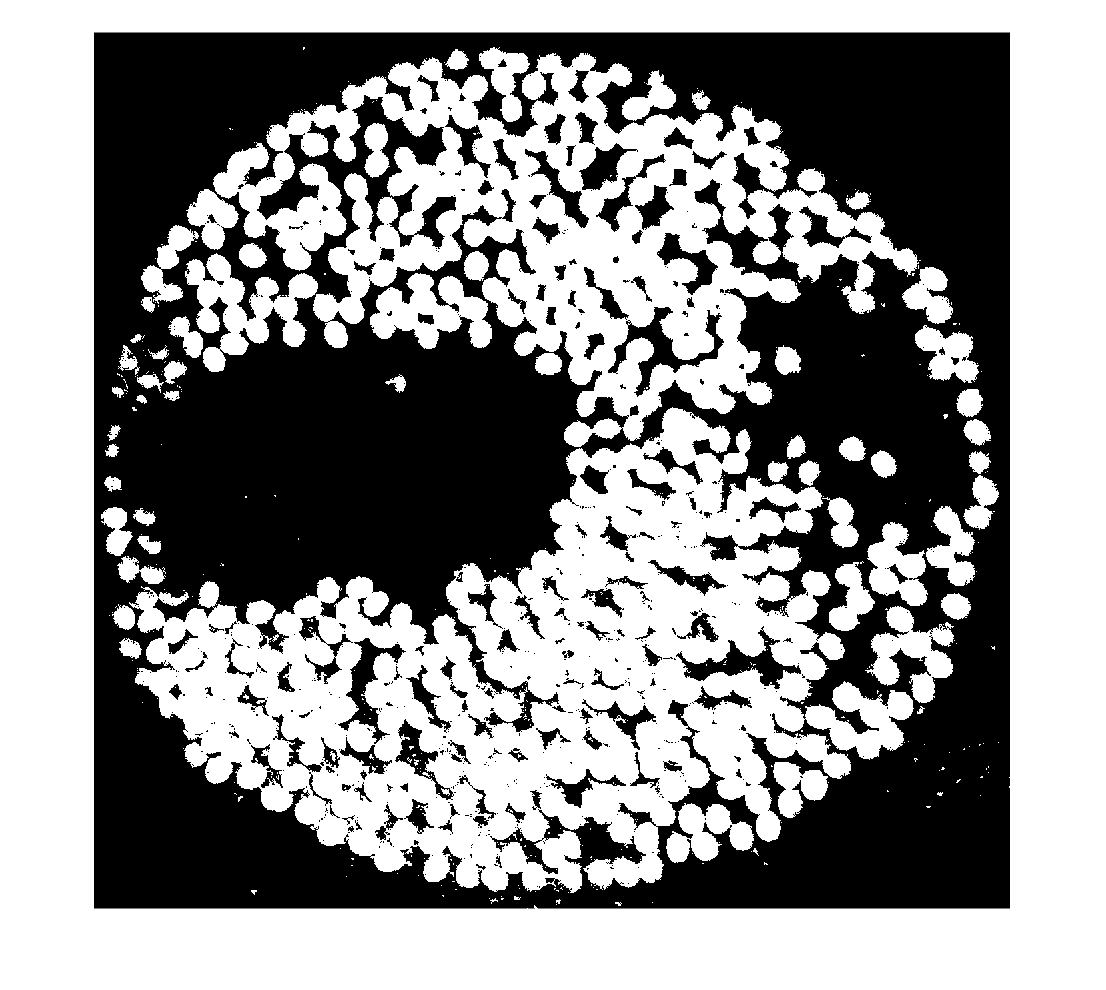


bw = imbinarize(img_gray, .6); imshow(bw);

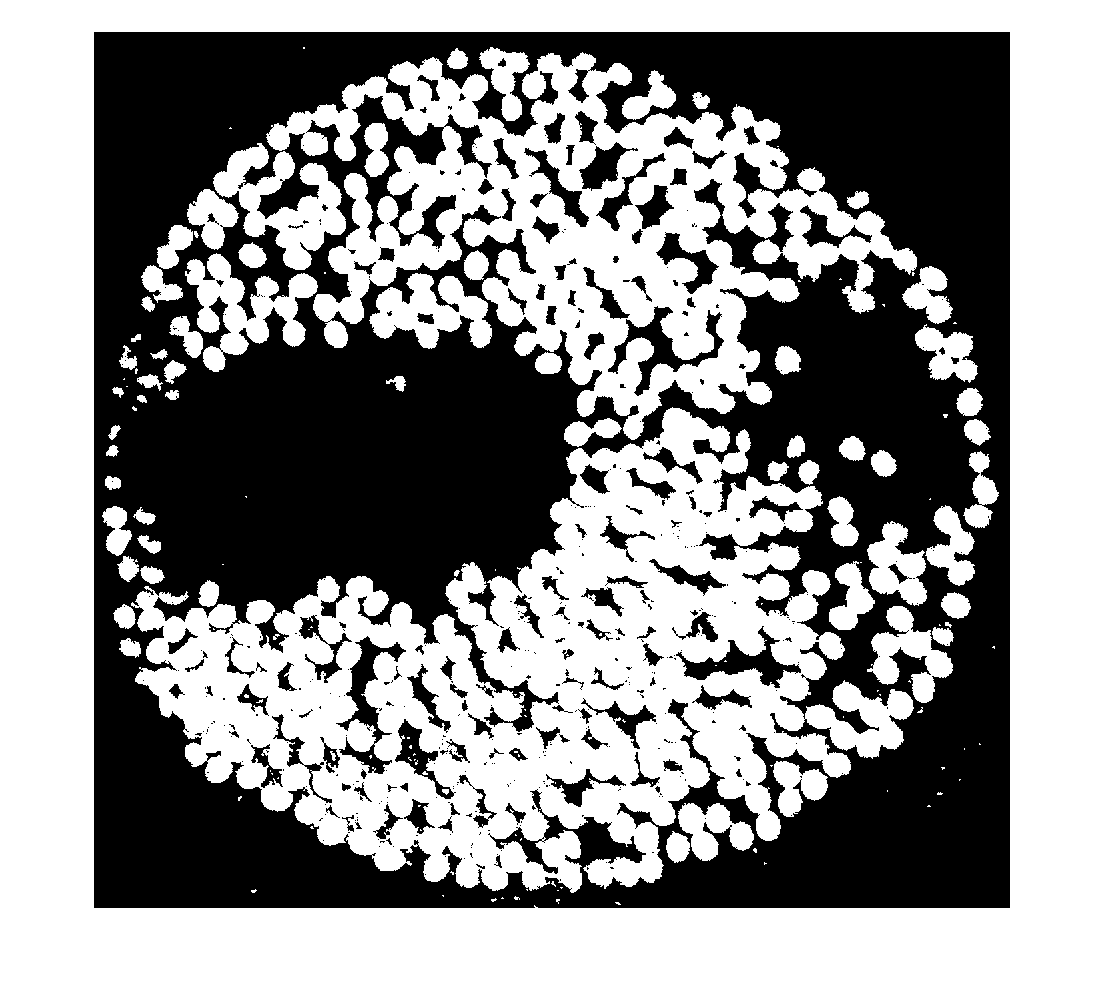


se = strel('disk', 1, 6);
img_erosion = imopen(bw, se);
imshow(img_erosion, []);

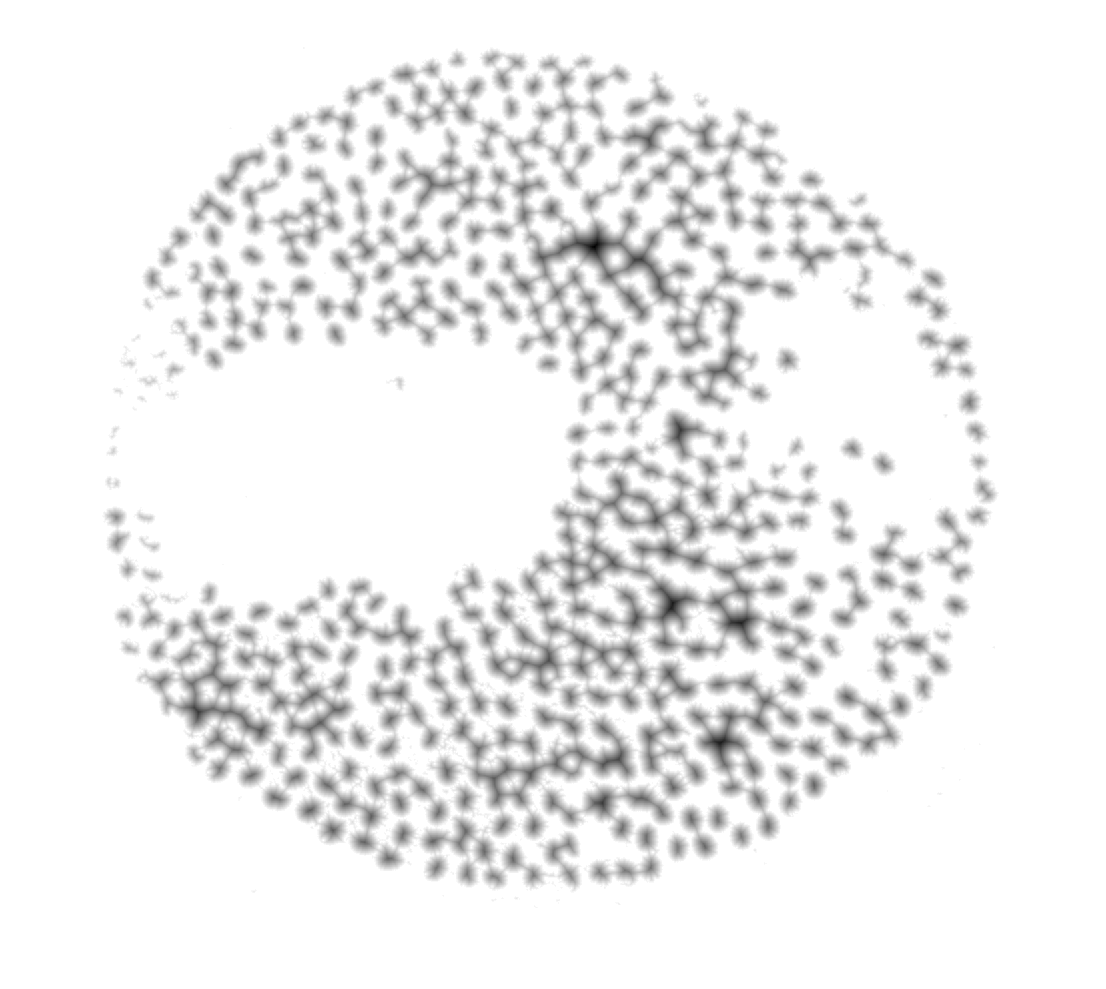


distance_transform = -bwdist(~img_erosion);
imshow(distance_transform,[]);

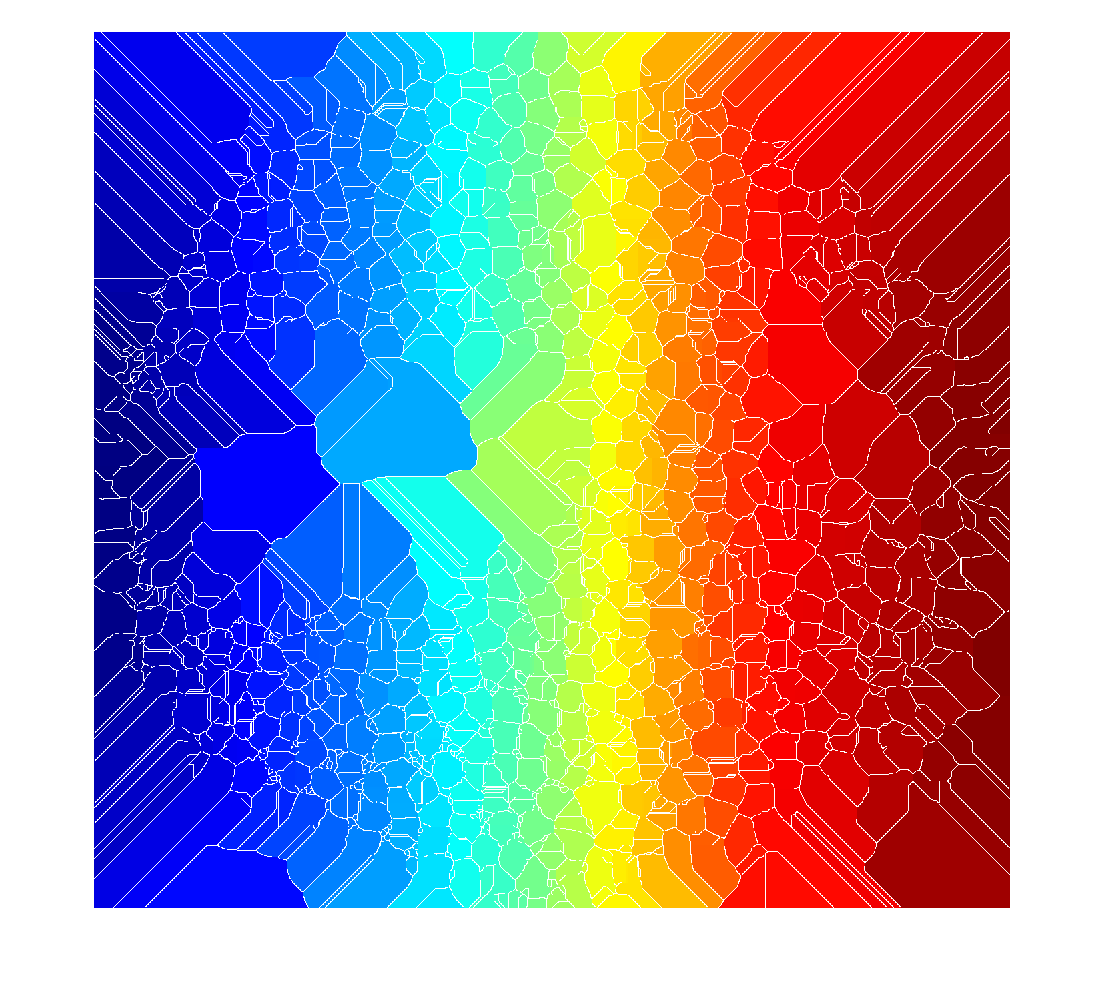


ws = watershed(distance_transform);
imshow(label2rgb(ws));

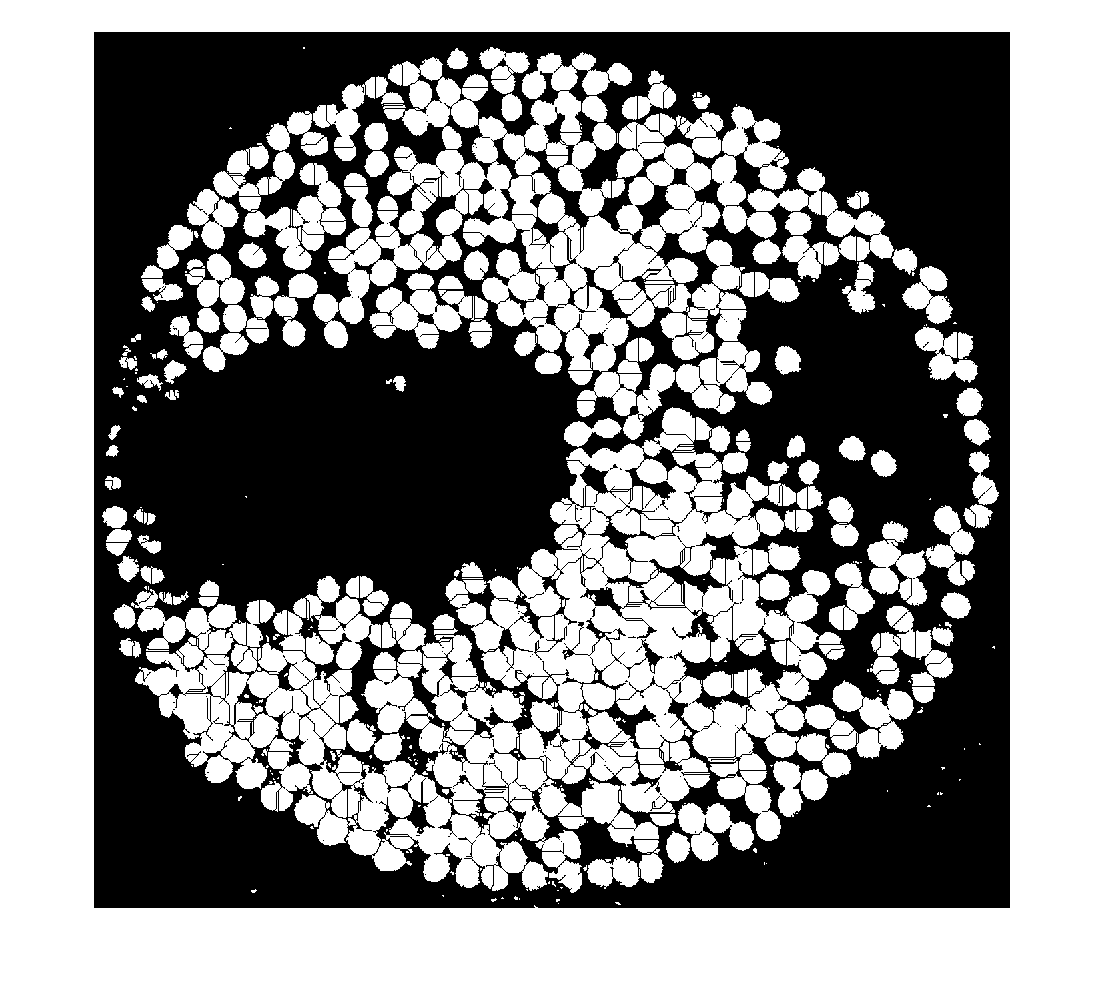


bw2 = img_erosion;
bw2(ws == 0) = 0;
imshow(bw2)

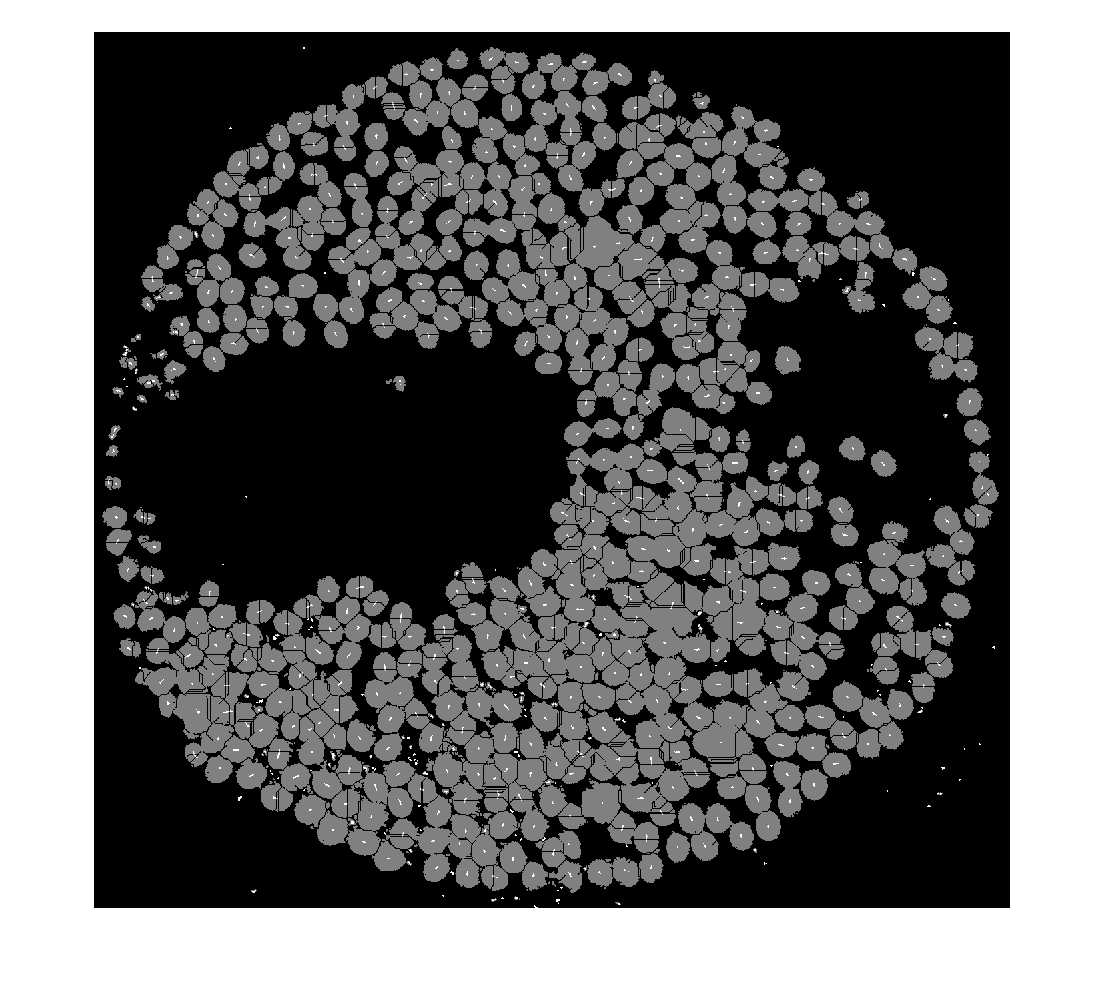


mask = imextendedmin(distance_transform, 1);
imshowpair(bw2, mask, 'blend')

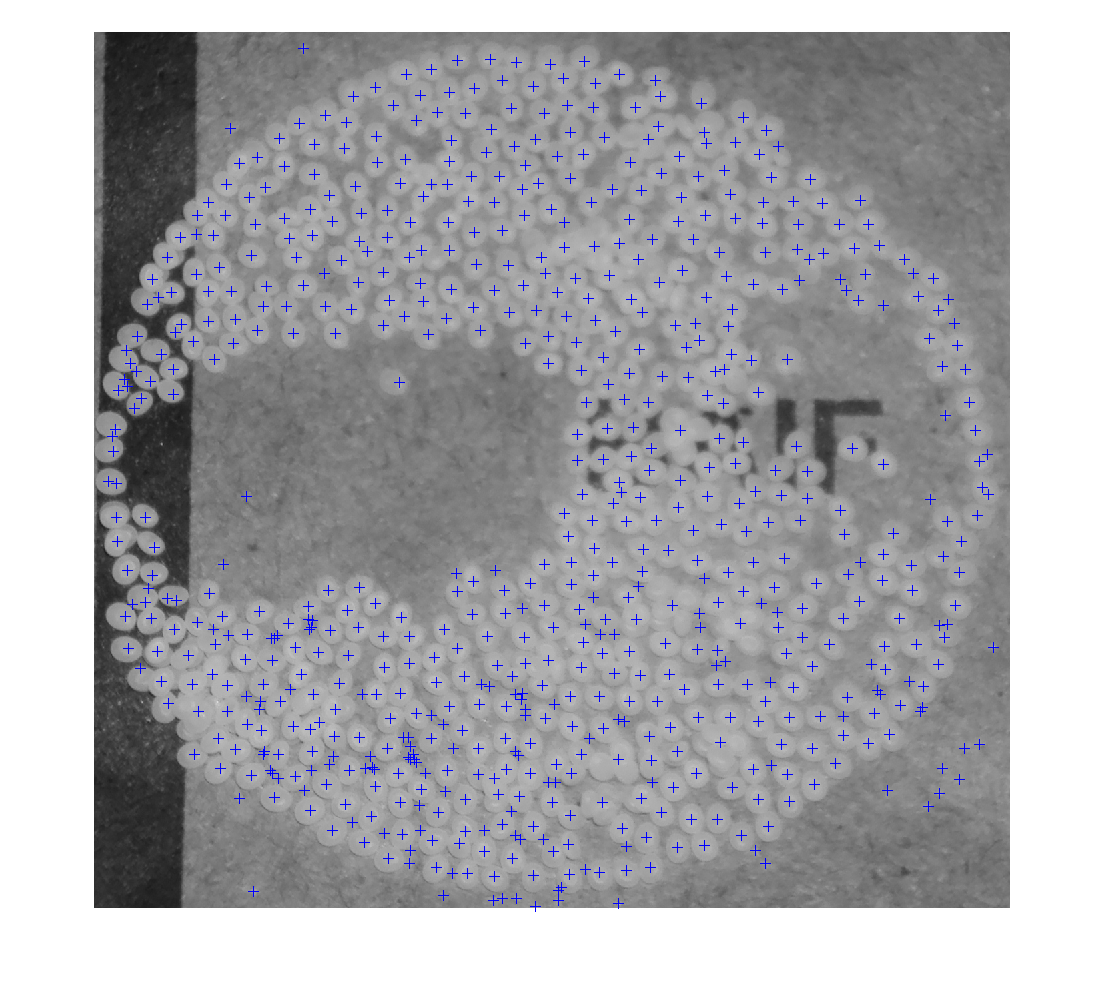


s  = regionprops(mask, 'centroid');
N_objects = numel(s);
centroids = cat(1,s.Centroid);
figure
imshow(img_gray);
hold on
plot(centroids(:,1), centroids(:,2), 'b+')
hold off


coins = bwconncomp(mask);
disp(coins.NumObjects);

   701

